This LiveScript is an intorduction to using the Mechanics Toolkit (name?)

First, declare all functions and parameters as symbolic. Functions need to be functions of $t$. 


clear all
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t) m1 m2 L g


Once those are declared, set up the problem as normal.  If you want to derive things in terms of general parameters, you may do so, as is demonstrated below. If you aren't 

intersted in deriving your equations in terms of general parameters, you may go ahead and define your parameters before anything else. 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

%Position of pendulum 1 and pendulum 2. 
rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];

%Force acting on pendulum 1 at the pivot F1, force acting on pendulum 1 at
%the connection to pendulum 1, F2, and force acting on pendulum 2 at the
%connection to pendulum 1, F3. 
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];


Now give the equations of motion for each pendulum. 


%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;


%Set up equations of motion.  NOTICE THE CONSTITUATIVE RELATION
%F2==-F3 goes in the DEs!  This is because that equation doesn't need to be
%differentiated.  Maybe we should do something about that for clarity?

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];


Now let's derive the equations of motion for the double pendulum in terms of general parameters.  This functionality is surprisingly powerful -- give it a try on some problems!

You supply the equations of motion (DES), the position constraints (as defined above), and velocity constraints (constraints that need to be differentiated only 1 time rather than 2). 

Then, you define which state variables you would like to use.  For this problem, the natural ones are $\theta_i$ and $\theta_i'$.   The output are the "governing DEs", as well as post-processing equations. The post processing equations express all other quantities of interest in terms of the specified state variables.  Naturally, you could give specific values to the parameters

first if you had a certain problem in mind. 

[governingDEs,ppes]=generateGoverningDEs(DES,PositionConstraints,[],[theta1,diff(theta1),theta2,diff(theta2)])

$$governingDEs = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=-\frac{9\,g\,m_{2}\,\sin\left(\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right)\right)+12\,g\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+15\,g\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)+12\,L\,m_{2}\,\sigma_{1}\,\sigma_{4}+9\,L\,m_{2}\,\sin\left(\sigma_{6}\right)\,\sigma_{2}}{\sigma_{5}}\\ \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=\frac{9\,g\,m_{1}\,\sigma_{3}-18\,g\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)-3\,g\,m_{1}\,\sin\left(\theta_{2}\left(t\right)\right)+18\,g\,m_{2}\,\sigma_{3}+12\,L\,m_{1}\,\sigma_{1}\,\sigma_{2}+36\,L\,m_{2}\,\sigma_{1}\,\sigma_{2}+9\,L\,m_{2}\,\sin\left(\sigma_{6}\right)\,\sigma_{4}}{\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=\sin\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{5}=L\,\left(8\,m_{1}+15\,m_{2}-9\,m_{2}\,\cos\left(\sigma_{6}\right)\right)\\ \sigma_{6}=2\,\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right) \end{array}$$

You need not use the canonical state variables.  For instance, use $x_1$, $x_1'$, $x_2$, and $x_2'$.  It is a bad idea, this takes forever to run, but if you wait long enough it does indeed produce a solution.

%generateGoverningDEs(DES,PositionConstraints,[],[theta1,diff(theta1),x2,diff(x2)])

Once you have a set of ODEs that govern the system, you can use `timeStepODESystem` to generate a trajectory.  If you've derived the equations with general parameters, you'll need to substitute in values prior to time stepping.  This is just a wrapper around `ODE45` that takes a symbolic system of ODEs rather than the typical function handle. If you supply the post-processing equations from `generateGoverningDEs`, then all of the quantities of interest described in the post processing equations will be calculated along with the state variables. If they aren't supplied, then obviously they won't be calculated. 

params.m1=4; params.m2=2;params.L=3; params.g=9.81;
traj=timeStepODESystem(subs(governingDEs,params),[0,10],[theta1==0.4,diff(theta1)==0,theta2==0,diff(theta2)==0.1],doPlot=0,...
    PostProcessFunctions=subs(ppes,params))

traj = struct with fields:
            t: [214×1 double]
       theta1: [214×1 double]
     Dtheta1t: [214×1 double]
       theta2: [214×1 double]
     Dtheta2t: [214×1 double]
    Dtheta1tt: [214×1 double]
    Dtheta2tt: [214×1 double]
         Dx1t: [214×1 double]
         Dx2t: [214×1 double]
        Dx1tt: [214×1 double]
        Dx2tt: [214×1 double]
         Dy1t: [214×1 double]
         Dy2t: [214×1 double]
        Dy1tt: [214×1 double]
        Dy2tt: [214×1 double]
          F1x: [214×1 double]
          F2x: [214×1 double]
          F3x: [214×1 double]
          F1y: [214×1 double]
          F2y: [214×1 double]
          F3y: [214×1 double]
           x1: [214×1 double]
           x2: [214×1 double]
           y1: [214×1 double]
           y2: [214×1 double]


Now you can plot whatever quantity you like. 

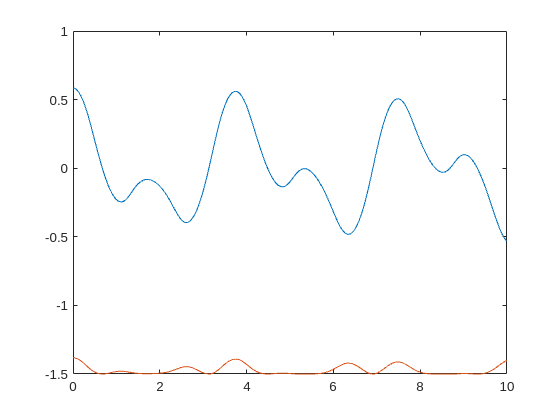

plot(traj.t,traj.x1,traj.t,traj.y1)

If you have a certain problem in mind, and you have the value of some variables at a certain moment in time, you may compute the value of the other quantities of interest at that moment in time.  This is completely separate from generating governing DEs.  You do not need to generate govering DEs in order to complete the state, you just need a complete description of the equations of motion. 


DES=subs(DES,params);
PositionConstraints=subs(PositionConstraints,params);


%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  

completeState(DES,PositionConstraints,[],{x1==0.5,theta2==pi/4,diff(x1)==1,diff(y2)==3})

ans = struct with fields:
         F1x: -15.6577
         F2x: 17.5381
         F3x: -17.5381
         F1y: 66.9618
         F2y: -23.8750
         F3y: 23.8750
      theta1: 0.3398
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: -1.4142
          y2: -3.8891
    Dtheta1t: 0.7071
    Dtheta2t: 2.1618
        Dx1t: 1
        Dx2t: 4.2929
        Dy1t: 0.3536
        Dy2t: 3


%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  If the partial state presented is inconsistent, then no
%complete state can be found. Note that the prescribed values of x1 and
%theta1 don't match. 

completeState(DES,PositionConstraints,[],{x1==0.5,theta1==pi/4,diff(x1)==1,diff(y2)==3})

Error using helpers/timeStepDAESystem/selectIC (line 533)
No suitable initial value for Dtheta1t found.


Error in helpers.timeStepDAESystem (line 391)
                ICsoln=selectIC(ICsoln,hintsStruct);

Error in 

%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  Here we are prescribing too much information, but it is
%consistent.  The solver warns us that we are probably over-determining,
%but succeeds. 

completeState(DES,PositionConstraints,[],{x1==sqrt(2)/2*3/2,theta1==pi/4,theta2==1,diff(x1)==1,diff(y2)==3})

ans = struct with fields:
         F1x: -31.7178
         F2x: 17.2246
         F3x: -17.2246
         F1y: 44.1898
         F2y: -11.9006
         F3y: 11.9006
      theta1: 0.7854
      theta2: 1
          x1: 1.0607
          x2: 3.3835
          y1: -1.0607
          y2: -2.9318
    Dtheta1t: 0.9428
    Dtheta2t: 0.7923
        Dx1t: 1
        Dx2t: 2.6421
        Dy1t: 1
        Dy2t: 3


%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  In this example there are multiple possible
%configurations, because we are only specifying the y-coordinate of
%pendulum 1. With no diagnostics, the solver just chooses an state and goes with it. 
%if diagnostics are turned on, then the solver warns us. 

completeState(DES,PositionConstraints,[],{x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,diff(theta2)==0})

ans = struct with fields:
         F1x: 8.6709
         F2x: -0.9091
         F3x: 0.9091
         F1y: 33.7911
         F2y: -3.6592
         F3y: 3.6592
      theta1: 2.8018
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: 1.4142
          y2: 1.7678
    Dtheta1t: 1
    Dtheta2t: 0
        Dx1t: -1.4142
        Dx2t: -2.8284
        Dy1t: 0.5000
        Dy2t: 1


%Turn on diagnostics to get warning. 
completeState(DES,PositionConstraints,[],{x1==0.5,theta2==pi/4,diff(theta1(t),t)==1,diff(theta2)==0},doDiagnostics=1)

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:-1.414214    Dx2t:-2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:2.801756    x2:2.060660    y1:1.414214    y2:1.767767    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
F1x: 8.670894
F2x: -0.909148
F3x: 0.909148
F1y: 33.791097
F2y: -3.659250
F3y: 3.659250
theta1: 2.801756 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:-1.414214
x2: 2.060660 x2t:-2.828427
y1: 1.414214 y1t:0.500000
y2: 1.767767 

ans = struct with fields:
         F1x: 8.6709
         F2x: -0.9091
         F3x: 0.9091
         F1y: 33.7911
         F2y: -3.6592
         F3y: 3.6592
      theta1: 2.8018
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: 1.4142
          y2: 1.7678
    Dtheta1t: 1
    Dtheta2t: 0
        Dx1t: -1.4142
        Dx2t: -2.8284
        Dy1t: 0.5000
        Dy2t: 1


%Select the other feasibile initial condition by saying that y1 should be near -1.  
completeState(DES,PositionConstraints,[],{x1==0.5,theta2==pi/4,diff(theta1(t),t)==1,diff(theta2)==0},...
    doDiagnostics=1, hints={y1==-1})

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:1.414214    Dx2t:2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:0.339837    x2:2.060660    y1:-1.414214    y2:-3.889087    
Because it is closest to satisfying the hints.

Initial Conditions:
Y0/YP0:
F1x: -15.314899
F2x: 11.582087
F3x: -11.582087
F1y: 61.099150
F2y: -16.814937
F3y: 16.814937
theta1: 0.339837 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:1.414214
x2: 2.060660 x2t:2.828427
y1: -1.414214 y1t:0.500000
y2: -3.889087 y2t:1.000000
Dtheta1t: 1.000000 D

ans = struct with fields:
         F1x: -15.3149
         F2x: 11.5821
         F3x: -11.5821
         F1y: 61.0992
         F2y: -16.8149
         F3y: 16.8149
      theta1: 0.3398
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: -1.4142
          y2: -3.8891
    Dtheta1t: 1
    Dtheta2t: 0
        Dx1t: 1.4142
        Dx2t: 2.8284
        Dy1t: 0.5000
        Dy2t: 1


Sometimes it will be difficult or impossible to generate the governing differential equations.  In this case, you can have a DAE solver timestep the equations of motion directly. This will produce all of the same information that `generateGoverningDEs` followed by `timeStepODESystem`. 

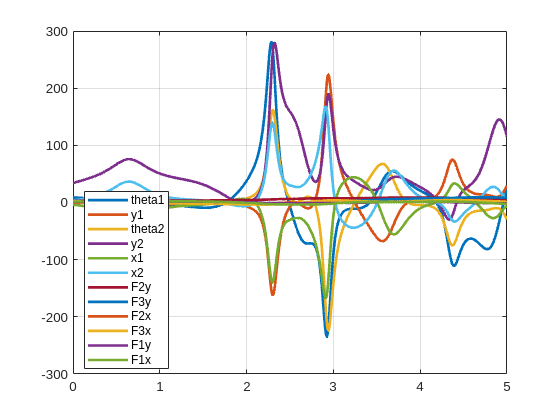

%Timestep the DAE directly.  The DEs of motion, the position constraints,
%velocity constraints, time interval, and initial conditions are not
%optional. 
soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"});

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:-1.414214    Dx2t:-2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:2.801756    x2:2.060660    y1:1.414214    y2:1.767767    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
F1x: 8.670894
F2x: -0.909148
F3x: 0.909148
F1y: 33.791097
F2y: -3.659250
F3y: 3.659250
theta1: 2.801756 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:-1.414214
x2: 2.060660 x2t:-2.828427
y1: 1.414214 y1t:0.500000
y2: 1.767767 


%Do the exact same thing as above, but print diagnostic information with
%the optional "doDiagnostics" option. 

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},doDiagnostics=1);

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:1.414214    Dx2t:2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:0.339837    x2:2.060660    y1:-1.414214    y2:-3.889087    
Because it is closest to satisfying the hints.

Initial Conditions:
Y0/YP0:
F1x: -15.314899
F2x: 11.582087
F3x: -11.582087
F1y: 61.099150
F2y: -16.814937
F3y: 16.814937
theta1: 0.339837 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:1.414214
x2: 2.060660 x2t:2.828427
y1: -1.414214 y1t:0.500000
y2: -3.889087 y2t:1.000000
Dtheta1t: 1.000000 D

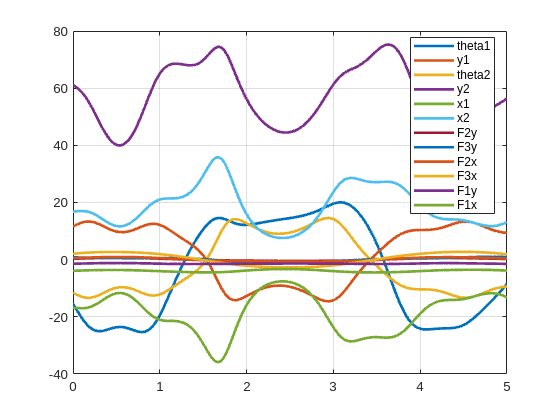

%In the example above, there was more than one feasible initial condition.
%Indicate which one to use using the option hints=

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},doDiagnostics=1,hints={y1==-1});

%Turn off the automatic plotting using the optional doPlot= option

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},hints={y1==-1},doPlot=0);


%Select the DAE solver to use.  Sometimes one solver will work and another
%won't. Options are "ode15s","ode23t","ode15i". 

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},hints={y1==-1},doPlot=0,solver="ode23t");


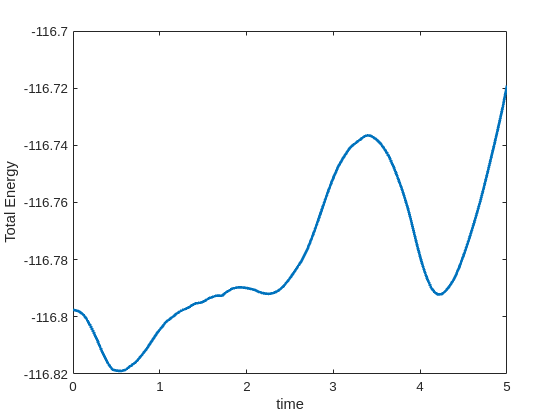




%See if we are conserving energy. 
KineticEnergy=subs(1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)...
    +1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2,params);
PotentialEnergy=subs(m1*soln.y1*g+m2*soln.y2*g,params);
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')